Import CSV file

clearvars;
% filename = 'Data/20230322_1/400V_1.0MSs_5ohm_17_20230322103933251.5V_5ohm_-3V_ALL.csv';
% filename = 'Data/20230322_1/400V_1.0MSs_5ohm_17_20230322104327251.5V_5ohm_-3V_ALL.csv';
filename = 'Data/FFT_Test/Pulse_60_Vds_350_Vgson_175_Vgsoff_30_ALL_20230425140645918.csv'

filename = 'Data/FFT_Test/Pulse_60_Vds_350_Vgson_175_Vgsoff_30_ALL_20230425140645918.csv'

data = readtable(filename);

Data parsing

data = renamevars(data, "Labels", "Time");
t = data.Time;
Vgs = data.Vgs;
Vds = data.Vds;
Id = data.Id;

figure;

subplot(3,1,1);
plot(t, Vgs);
ylabel("V_gs");
title("Original data");

subplot(3,1,2);
plot(t, Vds);
ylabel("V_ds");

subplot(3,1,3);
plot(t, Id);
ylabel("I_d");

Perform continuous wavelet transform

fs = length(t)/(t(length(t)) - t(1))

fs = 6.2500e+09

[cfs_Id, f_Id] = cwt(Id, 'Morse', fs);
[cfs_Vds, f_Vds] = cwt(Vds, 'Morse', fs);
[cfs_Vgs, f_Vgs] = cwt(Vgs, 'Morse', fs);

Plot CWT data

% figure;
% hold on;
% imagesc([t(1) t(length(t))], [f_Id(1) f_Id(length(f_Id)) ], abs(cfs_Id)); % Plot the CWT coefficients using imagesc
% colormap(jet); % Choose the colormap for the CWT coefficients plot
% colorbar; % Show the color bar for the CWT coefficients
% xlabel('Time (s)');
% ylabel('Frequency (Hz)');
% % set(gca, 'YScale', 'log'); % Set the y-axis to log scale to better visualize the frequency components
% ylim([min(f_Id) max(f_Id)]); % Set the y-axis limits to match the range of analyzed frequencies
% hold off;

Reconstruct the data

Id_recon = icwt(cfs_Id, 'Morse', f_Id, [min(f_Id) max(f_Id)]);

Plot the original and recontruct data

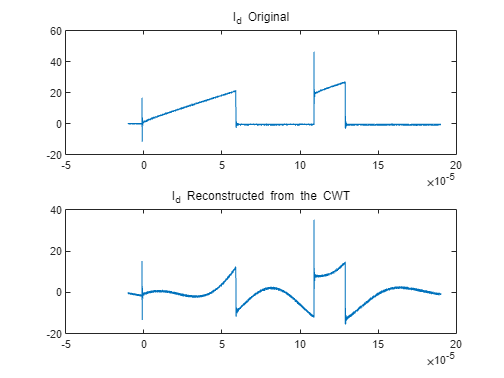

figure;

subplot(2,1,1);
plot(t, Id);
title("I_d Original");

subplot(2,1,2);
plot(t, Id_recon);
title("I_d Reconstructed from the CWT");

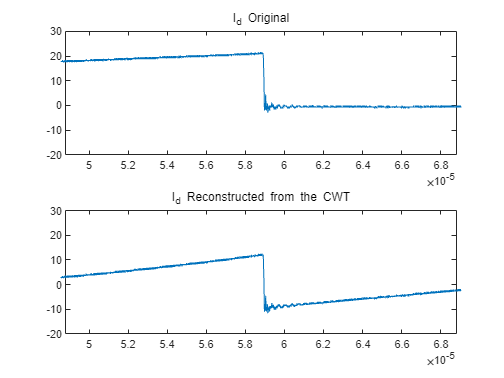

figure;
t_limit = 58.8e-6 + 10*[-1e-6 1e-6];

subplot(2,1,1);
plot(t, Id);
xlim(t_limit);
ylim([-20 30]);
title("I_d Original");

subplot(2,1,2);
plot(t, Id_recon);
xlim(t_limit);
ylim([-20 30]);
title("I_d Reconstructed from the CWT");

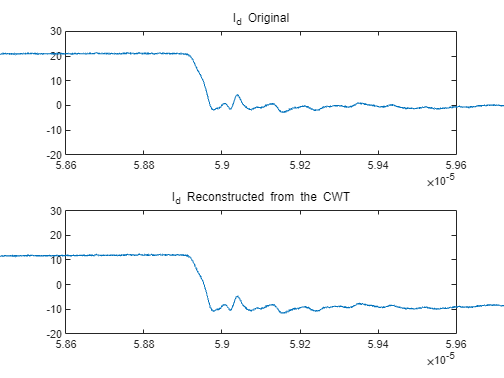

figure;
t_limit = 59.1e-6 + 0.5*[-1e-6 1e-6];

subplot(2,1,1);
plot(t, Id);
xlim(t_limit);
ylim([-20 30]);
title("I_d Original");

subplot(2,1,2);
plot(t, Id_recon);
xlim(t_limit);
ylim([-20 30]);
title("I_d Reconstructed from the CWT");

num_columns_resampled = 1250000/50; % New number of columns
resample_factor = size(cfs_Id, 2) / num_columns_resampled;

t_res = resample(t.', 1, resample_factor).';
cfs_Id_res = resample(cfs_Id.', 1, resample_factor).';
Id_res = resample(Id.', 1, resample_factor).';

tempcfs = double(cfs_Id_res);
sizeof_cfs_Id_res_double = (whos("tempcfs").bytes);
cfs_Id_res = single(cfs_Id_res);
sizeof_Id = (whos('Id').bytes);
sizeof_cfs_Id_res_single = (whos('cfs_Id_res').bytes);
sizeof_cfs_Id = (whos('cfs_Id').bytes);
disp("Id:                   " + sizeof_Id/1e6 + "MB"),...
    disp("cfs_Id:               " + sizeof_cfs_Id/1e6 + "MB"),...
    disp("cfs_Id_res_double:    " + sizeof_cfs_Id_res_double/1e6 + "MB"),...
    disp("cfs_Id_res_single:    " + sizeof_cfs_Id_res_single/1e6 + "MB")

Id:                   10MB


cfs_Id:               3480MB


cfs_Id_res_double:    69.6MB


cfs_Id_res_single:    34.8MB


cfs_Id_res = double(cfs_Id_res);

original_num_columns = 1250000;
resample_factor_restore = original_num_columns / num_columns_resampled;

cfs_Id_res_res = resample(cfs_Id_res.', resample_factor_restore, 1).';

% Now 'data_restored' is a 174x1250000 complex double matrix

Id_res_res_recon = icwt(cfs_Id_res_res, 'Morse', f_Id, [min(f_Id) max(f_Id)]);

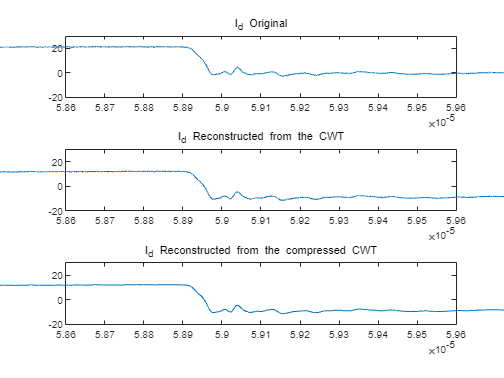

figure;
t_limit = 59.1e-6 + 0.5*[-1e-6 1e-6];

subplot(3,1,1);
plot(t, Id);
xlim(t_limit);
ylim([-20 30]);
title("I_d Original");

subplot(3,1,2);
plot(t, Id_recon);
xlim(t_limit);
ylim([-20 30]);
title("I_d Reconstructed from the CWT");

subplot(3,1,3);
plot(t, Id_res_res_recon);
xlim(t_limit);
ylim([-20 30]);
title("I_d Reconstructed from the compressed CWT");

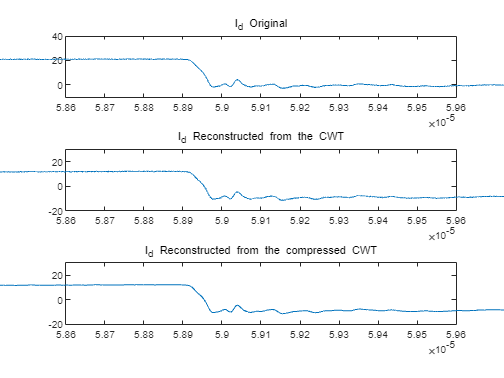

figure;
t_limit = 59.1e-6 + 0.5*[-1e-6 1e-6];

subplot(3,1,1);
plot(t, Id);
xlim(t_limit);
ylim([-10 40]);
title("I_d Original");

subplot(3,1,2);
plot(t, Id_recon);
xlim(t_limit);
ylim([-20 30]);
title("I_d Reconstructed from the CWT");

subplot(3,1,3);
plot(t, Id_res_res_recon);
xlim(t_limit);
ylim([-20 30]);
title("I_d Reconstructed from the compressed CWT");

Voice Per Octave test

[cfs_Id_vpo_1, f_Id_vpo_1] = cwt(Id, 'Morse', fs, VoicePerOctave=1);
[cfs_Id_vpo_5, f_Id_vpo_5] = cwt(Id, 'Morse', fs, VoicePerOctave=5);
[cfs_Id_vpo_10, f_Id_vpo_10] = cwt(Id, 'Morse', fs, VoicePerOctave=10);
[cfs_Id_vpo_15, f_Id_vpo_15] = cwt(Id, 'Morse', fs, VoicePerOctave=15);
[cfs_Id_vpo_20, f_Id_vpo_20] = cwt(Id, 'Morse', fs, VoicePerOctave=20);

Id_vpo_1_recon = icwt(cfs_Id_vpo_1, 'Morse', f_Id_vpo_1, [min(f_Id_vpo_1) max(f_Id_vpo_1)]);
Id_vpo_5_recon = icwt(cfs_Id_vpo_5, 'Morse', f_Id_vpo_5, [min(f_Id_vpo_5) max(f_Id_vpo_5)]);
Id_vpo_10_recon = icwt(cfs_Id_vpo_10, 'Morse', f_Id_vpo_10, [min(f_Id_vpo_10) max(f_Id_vpo_10)]);

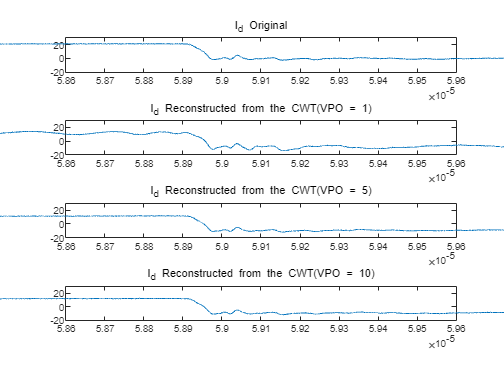

figure;
t_limit = 59.1e-6 + 0.5*[-1e-6 1e-6];

subplot(4,1,1);
plot(t, Id);
xlim(t_limit);
ylim([-20 30]);
title("I_d Original");

subplot(4,1,2);
plot(t, Id_vpo_1_recon);
xlim(t_limit);
ylim([-20 30]);
title("I_d Reconstructed from the CWT(VPO = 1)");

subplot(4,1,3);
plot(t, Id_vpo_5_recon);
xlim(t_limit);
ylim([-20 30]);
title("I_d Reconstructed from the CWT(VPO = 5)");

subplot(4,1,4);
plot(t, Id_vpo_10_recon);
xlim(t_limit);
ylim([-20 30]);
title("I_d Reconstructed from the CWT(VPO = 10)");

num_columns_resampled = 1250000/50; % New number of columns
resample_factor = size(cfs_Id_vpo_5, 2) / num_columns_resampled;

t_res = resample(t.', 1, resample_factor).';
cfs_Id_vpo_5_res = resample(cfs_Id_vpo_5.', 1, resample_factor).';
Id_res = resample(Id.', 1, resample_factor).';

original_num_columns = 1250000;
resample_factor_restore = original_num_columns / num_columns_resampled;

cfs_Id_vpo_5_res_res = resample(cfs_Id_vpo_5_res.', resample_factor_restore, 1).';
Id_vpo_5_res_res_recon = icwt(cfs_Id_vpo_5_res_res, 'Morse', f_Id_vpo_5, [min(f_Id_vpo_5) max(f_Id_vpo_5)]);

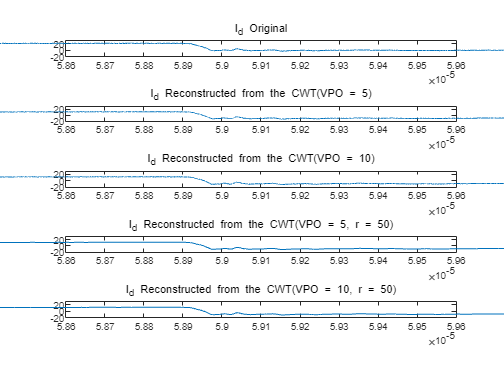

figure;
t_limit = 59.1e-6 + 0.5*[-1e-6 1e-6];

subplot(5,1,1);
plot(t, Id);
xlim(t_limit);
ylim([-20 30]);
title("I_d Original");

subplot(5,1,2);
plot(t, Id_vpo_5_recon);
xlim(t_limit);
ylim([-20 30]);
title("I_d Reconstructed from the CWT(VPO = 5)");

subplot(5,1,3);
plot(t, Id_vpo_10_recon);
xlim(t_limit);
ylim([-20 30]);
title("I_d Reconstructed from the CWT(VPO = 10)");

subplot(5,1,4);
plot(t, Id_vpo_5_res_res_recon);
xlim(t_limit);
ylim([-20 30]);
title("I_d Reconstructed from the CWT(VPO = 5, r = 50)");

subplot(5,1,5);
plot(t, Id_res_res_recon);
xlim(t_limit);
ylim([-20 30]);
title("I_d Reconstructed from the CWT(VPO = 10, r = 50)");

sizeof_cfs_Id_vpo_5_res_double = (whos('cfs_Id_vpo_5_res').bytes);
disp("cfs_Id_vpo_5_res_double:    " + sizeof_cfs_Id_vpo_5_res_double/1e6 + "MB");

cfs_Id_vpo_5_res_double:    34.8MB


X_Id = [Id Id_vpo_5_recon' Id_vpo_10_recon' Id_vpo_5_res_res_recon' Id_res_res_recon'];

X_Id_mean =     5.4377    0.0000    0.0000    0.0001    0.0000


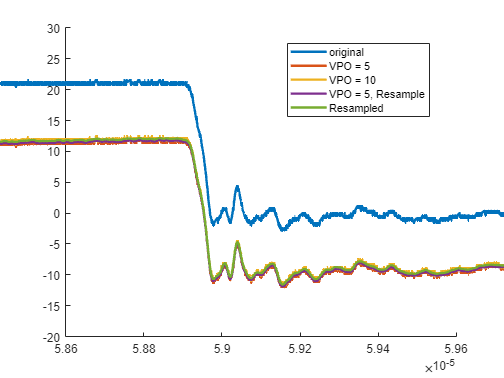

figure;
hold on;
t_limit = 59.1e-6 + 0.5*[-1e-6 1e-6];
for i = 1:length(X_Id(1, :))
    plot(t, X_Id(:, i), LineWidth=2)
end
% plot(t, Id, LineWidth=1);
% plot(t, Id_vpo_5_recon, LineWidth=1);
% plot(t, Id_vpo_10_recon, LineWidth=1);
% plot(t, Id_vpo_5_res_res_recon, LineWidth=2);
% plot(t, Id_res_res_recon, LineWidth=2);
xlim(t_limit);
ylim([-20 30]);
legend("original", "VPO = 5", "VPO = 10", "VPO = 5, Resample", "Resampled", 'Location', 'best')
hold off

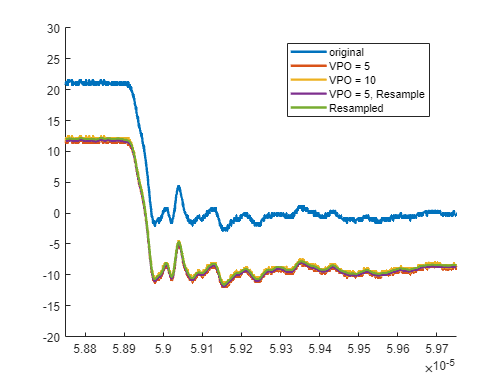

t_limit = 59.25e-6 + 0.5*[-1e-6 1e-6];
t_index = (t_limit(1) < t) & (t < t_limit(2));
t_sample = t(t_index);
X_Id_sample = X_Id(t_index, :);
figure;
hold on;
for i = 1:length(B_Id_sample(1, :))
    plot(t_sample, X_Id_sample(:, i), LineWidth=2)
end
xlim(t_limit);
ylim([-20 30]);
legend("original", "VPO = 5", "VPO = 10", "VPO = 5, Resample", "Resampled", 'Location', 'best')
hold off

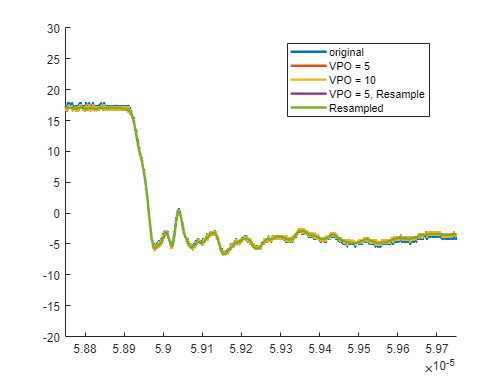

X_Id_sample_mean = mean(X_Id_sample);
B_Id_sample = X_Id_sample - X_Id_sample_mean;
figure;
hold on;
for i = 1:length(B_Id_sample(1, :))
    plot(t_sample, B_Id_sample(:, i), LineWidth=2)
end
xlim(t_limit);
ylim([-20 30]);
legend("original", "VPO = 5", "VPO = 10", "VPO = 5, Resample", "Resampled", 'Location', 'best')
hold off

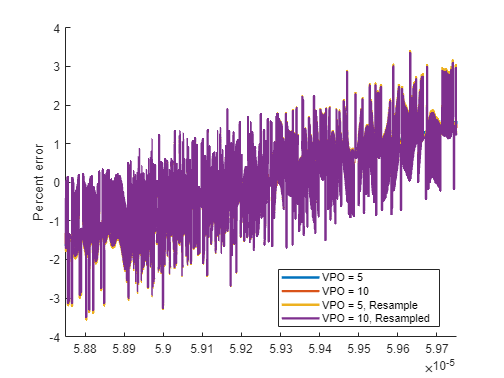

E_Id_sample = B_Id_sample - B_Id_sample(:,1);
Original_sample_range = range(B_Id_sample(:,1));
figure;
hold on;
% for i = 1:length(E_Id_sample(1, :))
for i = 2:length(E_Id_sample(1, :))
    plot(t_sample, E_Id_sample(:, i)./Original_sample_range * 100, '-', LineWidth=2)
end
xlim(t_limit);
ylabel("Percent error")
legend("VPO = 5", "VPO = 10", "VPO = 5, Resample", "VPO = 10, Resampled", 'Location', 'best')
hold off

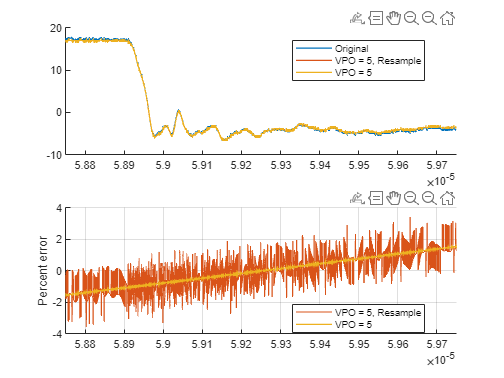

E_Id_sample = B_Id_sample - B_Id_sample(:,1);
Original_sample_range = range(B_Id_sample(:,1));

figure;

subplot(2,1,1)
hold on;
for i = [1, 4, 2]
    plot(t_sample, B_Id_sample(:, i), LineWidth=1)
end
xlim(t_limit);
legend("Original", "VPO = 5, Resample", "VPO = 5", 'Location', 'best')
hold off

subplot(2,1,2)
hold on;
% for i = 1:length(E_Id_sample(1, :))
for i = [1, 4, 2]
    plot(t_sample, E_Id_sample(:, i)./Original_sample_range * 100, '-', LineWidth=1)
end
xlim(t_limit);
ylabel("Percent error")
legend("", "VPO = 5, Resample", "VPO = 5", 'Location', 'best');
grid on;
hold off

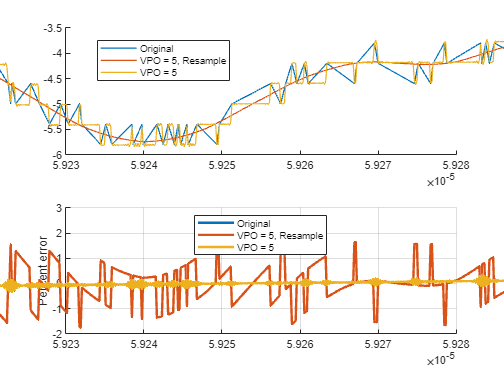

figure;
t_limit_narrow = 59.255e-6 + 0.025*[-1e-6 1e-6];
subplot(2,1,1)
hold on;
for i = [1, 4, 2]
    plot(t_sample, B_Id_sample(:, i), LineWidth=1)
end
xlim(t_limit_narrow);
legend("Original", "VPO = 5, Resample", "VPO = 5", 'Location', 'best');
hold off

subplot(2,1,2)
hold on;
% for i = 1:length(E_Id_sample(1, :))
for i = [1, 4, 2]
    plot(t_sample, E_Id_sample(:, i)./Original_sample_range * 100, '-', LineWidth=2)
end
xlim(t_limit_narrow);
ylim([-2 3])
ylabel("Percent error")
legend("Original", "VPO = 5, Resample", "VPO = 5", 'Location', 'north')
grid on;
hold off